*"commented for your proposed pipeline, with any functions you use; especially any parameters which you have found."*

*"It is expected that you write task specific functions for each major step in the image processing pipeline (i.e functions for handling major processing steps)"*

*"justify any functions used / developed within the submitted report."*

-     *starfish.jpg*

- *    starfish_noise#*

- *    starfish_map#*

- *    starfish5 or 17.*

# Input

Accept a file path and load the image to input into your implemented pipeline.

**Specifiy input image.**

imagePath = "images\starfish_noise5.jpg";

**Load and show image.**

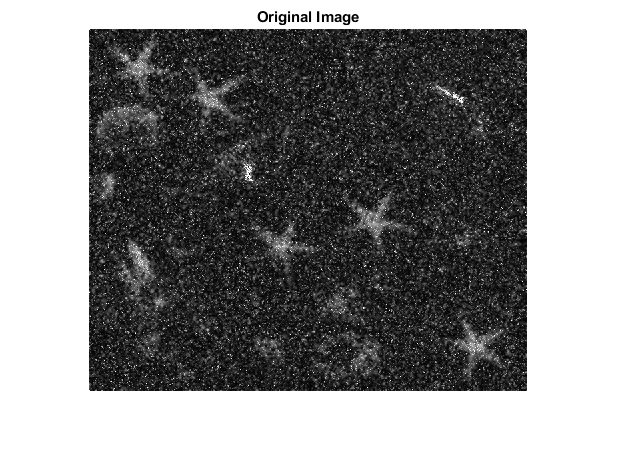

im = imread(imagePath);
im = rgb2hsv(im);
[c1,c2,c3] = imsplit(im);
im = c2;
imshow(im);
title("Original Image");

# Processing

Enhance input images and extract features.

**Denoise by detecting pixes that are locally different (isolated).**

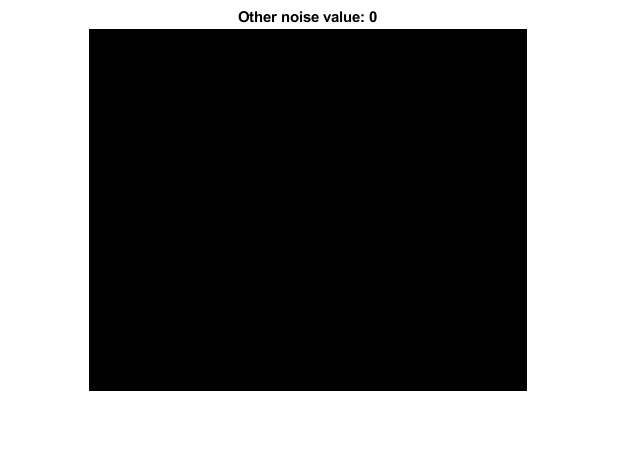

Method used: meanfilter


[im1, noise] = DenoiseIsolated(im, 'medianfilter');

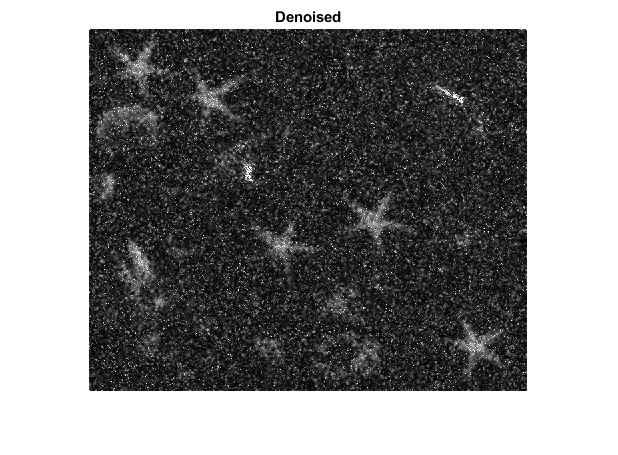

imshow(im1);
title("Denoised");

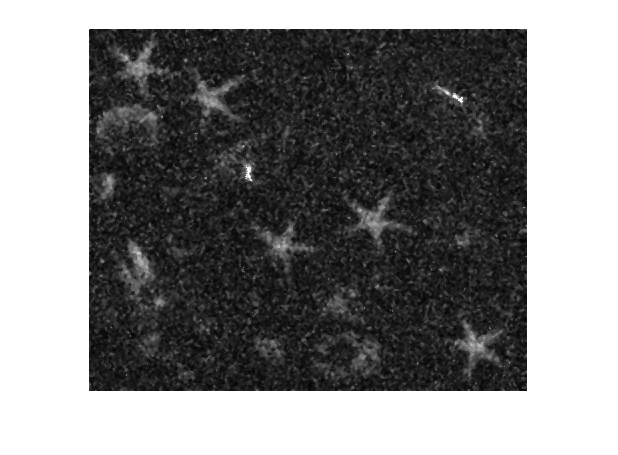


im  = medfilt3(im);
imshow(im);

???

# Analysis

Segment enhanced image.

% level = graythresh(im);
% im = imbinarize(im, level);
% imshow(im2double(im))
%
% lapFilt = conv2(double(im), filter, 'same');
% imshow(lapFilt)
%
% lapFilt = ~lapFilt;
% imshow(lapFilt)
%
% % Morphological ops
% se = strel('disk', 2);
% lapFilt = imerode(lapFilt, se);
% imshow(lapFilt);

# Recognition

Count identified objects and draw bounding boxes.

# *-Functions-*

function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %


function noisePercent = GetRelPercentageNoise(im, noiseMask)
noisyPixels = sum(noiseMask(:));
nPx = numel(im);
noisePercent = (100/nPx) * noisyPixels;
end
% % % %


function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;

    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
%     if (noiseValue > 30)
%         disp("Switching mode");
%         method = "meanfilter";
%         repeat = true;
%     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %


function filepaths = GetFilesInSubDir(subDir)
files = dir(subDir);
files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
filepaths = subDir + "\" + {files.name};
end
% % % %
